# rojTop view plot

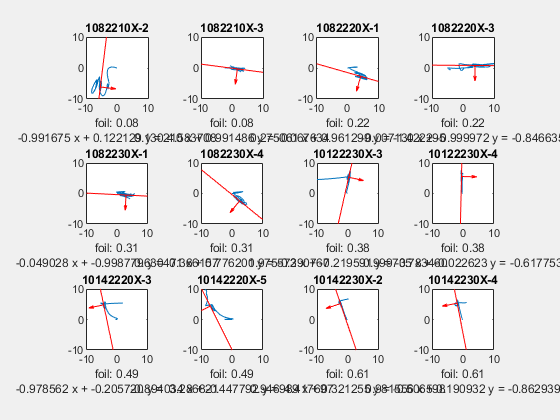

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
        % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        ax(i) = subplot(3,4,i);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        hold on;
        quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        title(FileName{i});
        xlim([-10, 10]);
        ylim([-10, 10]);
        xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('10_oil_TopViewTraj.fig')

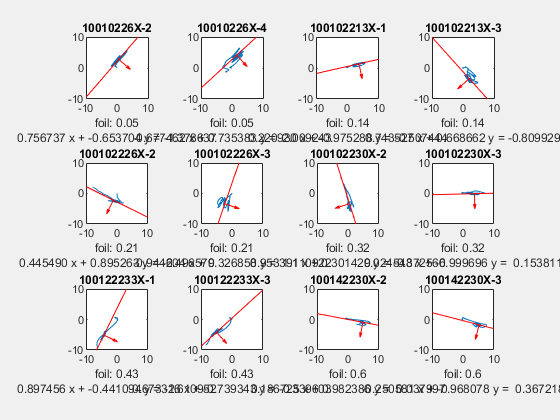

figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
       % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        subplot(3,4,i-12);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        hold on;
        quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        title(FileName{i});
        xlim([-10, 10]);
        ylim([-10, 10]);
        xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('100_oil_TopViewTraj.fig')

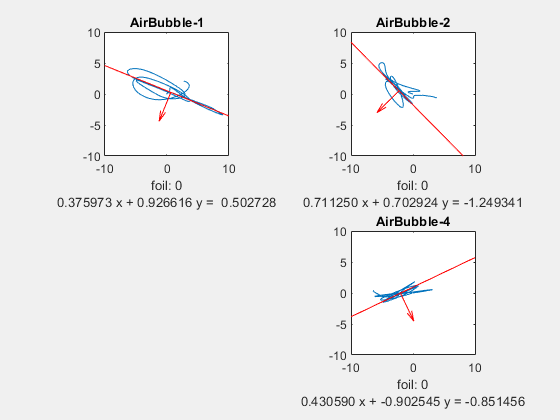

figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
         % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        subplot(2,2,i-24);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        hold on;
        quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        title(FileName{i});
        xlim([-10, 10]);
        ylim([-10, 10]);
        xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('Air_TopViewTraj.fig')

clear all
DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'

DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'

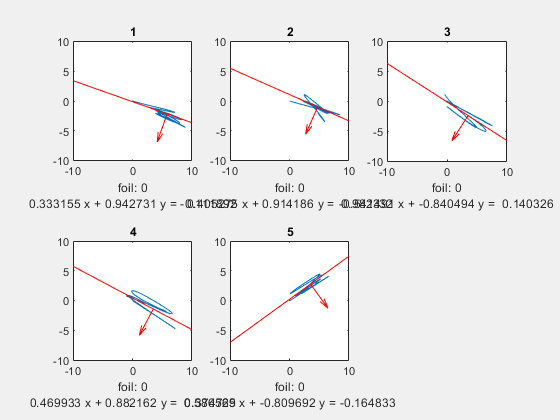

figure('visible','on');
clf;
for i = 1:5
    path = [DataPath, num2str(i), '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
        % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        ax(i) = subplot(2,3,i);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        hold on;
        quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        title(num2str(i));
        xlim([-10, 10]);
        ylim([-10, 10]);
        xlabel({['foil: ', num2str(0)]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('Air_New_TopViewTraj.fig')

## Sideview projection plot

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = Plane(3);
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
        yV = [0, -1];
        theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
        if -1/AntiSlope/LengthUnit < 0
            theta = -theta
        end
        ax(i) = subplot(3,4,i);
        plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        xlim([-10, 10]);
        ylim([-10, 10]);
        zlim([0, 200]);
        view(theta, 0);
        title(FileName{i});
    end
end

theta = -7.4817

theta = -15.9677

theta = -0.4085

theta = -2.8103

theta = -39.0853

theta = -78.1278

theta = -63.3952

theta = -71.2611

theta = -78.9923

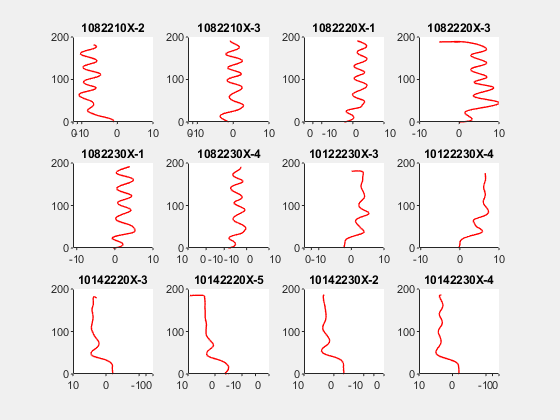

savefig('BestPlaneView10Oil.fig')

figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = Plane(3);
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
        yV = [0, -1];
        theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
        if -1/AntiSlope/LengthUnit < 0
            theta = -theta
        end
        ax(i) = subplot(3,4,i - 12);
        plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        xlim([-10, 10]);
        ylim([-10, 10]);
        zlim([0, 200]);
        view(theta, 0);
        title(FileName{i});
    end
end

theta = -48.0346

theta = -26.4553

theta = -72.4549

theta = -10.7620

theta = -14.5122

savefig('BestPlaneView100Oil.fig')
figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = Plane(3);
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
        yV = [0, -1];
        theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
        if -1/AntiSlope/LengthUnit < 0
            theta = -theta
        end
        ax(i) = subplot(2,2,i - 24);
        plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        xlim([-10, 10]);
        ylim([-10, 10]);
        zlim([0, 200]);
        view(theta, 0);
        title(FileName{i});
    end
end

theta = -22.0848

theta = -45.3373

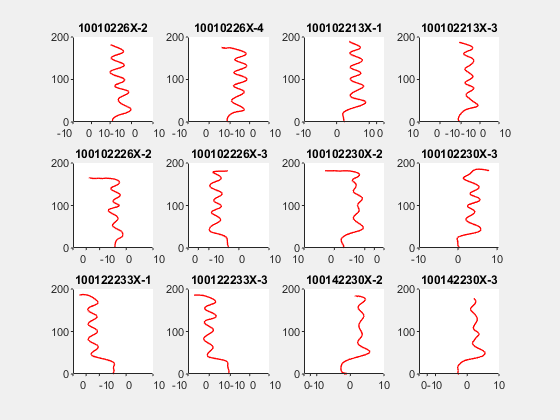

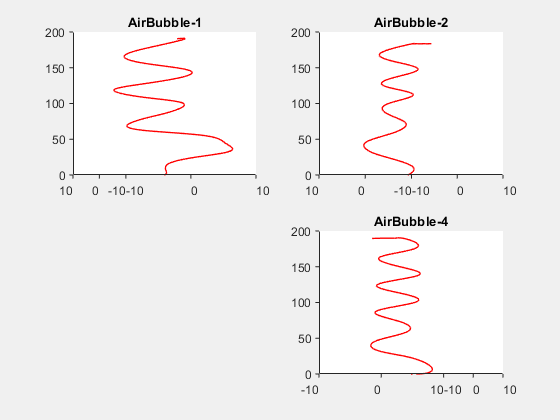

savefig('BestPlaneViewAir.fig')

clear all
DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'

DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'

figure('visible','on');
clf;
for i = 1:5
    path = [DataPath, num2str(i), '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = Plane(3);
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
        yV = [0, -1];
        theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
        if -1/AntiSlope/LengthUnit < 0
            theta = -theta
        end
        ax(i) = subplot(2,3,i);
        plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        xlim([-10, 10]);
        ylim([-10, 10]);
        zlim([0, 200]);
        view(theta, 0);
        title(num2str(i));
    end
end

theta = -19.4631

theta = -23.9086

theta = -32.7918

theta = -28.0445

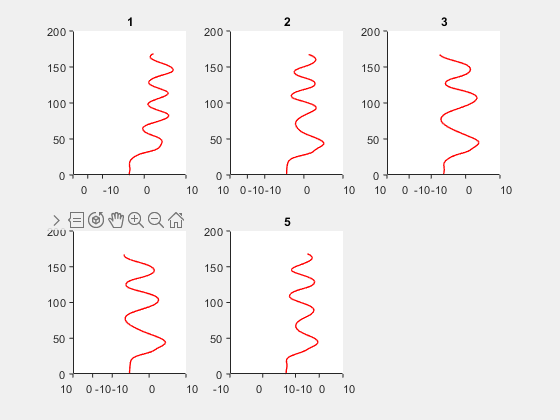

savefig('BestPlaneViewAirNew.fig')

## Velocity analysis

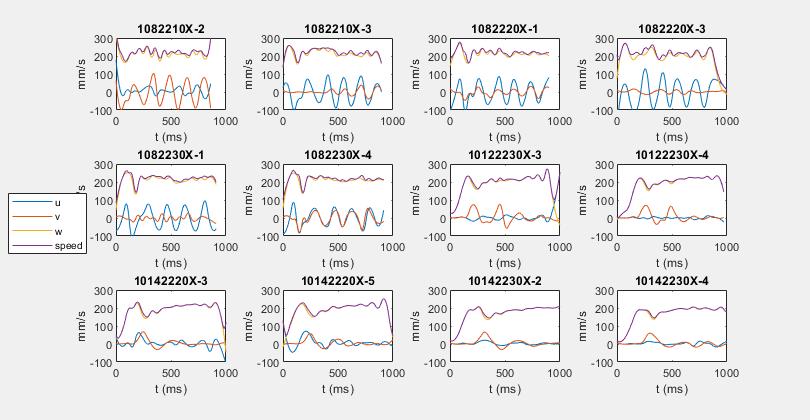

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(3,4,i);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('Velocity10oil.fig')
saveas(gcf,'Velocity10oil.png')

figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(3,4,i-12);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('Velocity100oil.fig')
saveas(gcf,'Velocity100oil.png')

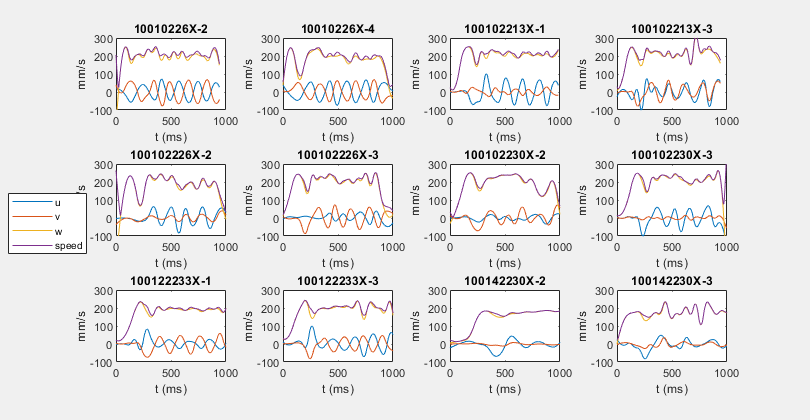

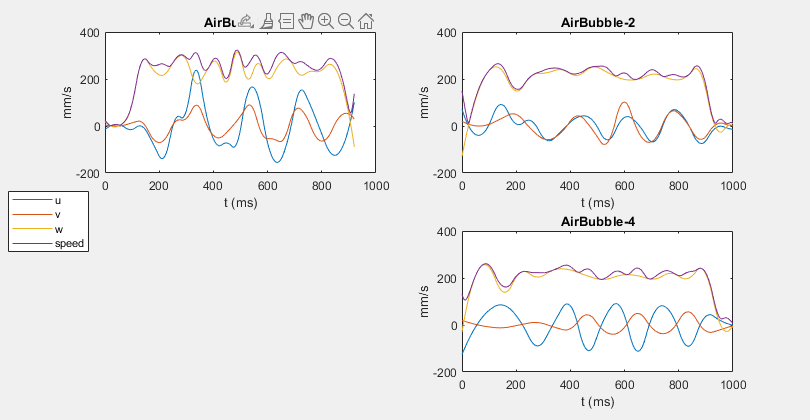

figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(2,2,i-24);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('VelocityAir.fig')
saveas(gcf,'VelocityAir.png')

clear all
DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'

DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'

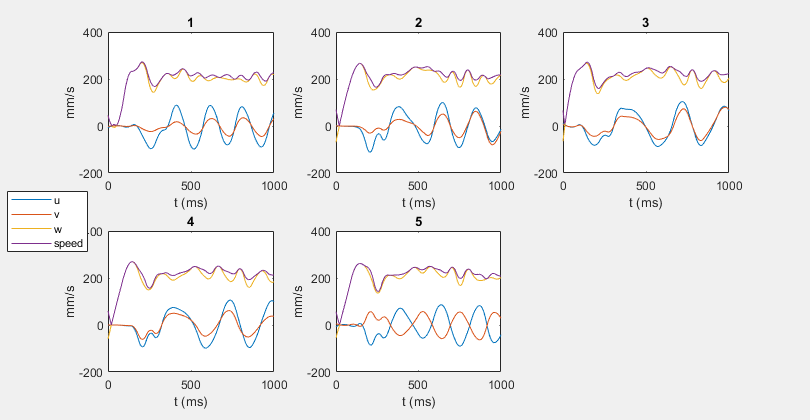

figure('visible','on');
clf;
for i = 1:5
    path = [DataPath, num2str(i), '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(2,3,i);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(num2str(i));
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('VelocityAirNew.fig')
saveas(gcf,'VelocityAirNew.png')

## Transverse speed analysis

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end

Tspeed =   188.1593
  150.6163
  119.6475
   96.5905
   82.8623
   78.5260
   81.0863
   86.8338
   92.8058
   97.2000


Tspeed =    26.4712
   34.8284
   41.6506
   46.7068
   49.9136
   51.2342
   50.6504
   48.1523
   43.7356
   37.4002


Tspeed =   112.5326
  103.5990
   94.4401
   85.0436
   75.3982
   65.4934
   55.3204
   44.8722
   34.1476
   23.1619


Tspeed =   191.9548
  159.4342
  129.3162
  101.6011
   76.2892
   53.3814
   32.8806
   14.8024
    1.5857
   14.3177


Tspeed =    71.6794
   70.3757
   68.1867
   65.1054
   61.1270
   56.2496
   50.4741
   43.8065
   36.2631
   27.8884


Tspeed =    89.8480
   88.8598
   86.8019
   83.6537
   79.3995
   74.0272
   67.5282
   59.8964
   51.1288
   41.2279


Tspeed =     3.5239
    2.7377
    2.0571
    1.4912
    1.0634
    0.8226
    0.8057
    0.9489
    1.1602
    1.4023


Tspeed =     0.8069
    0.8402
    0.8774
    0.9123
    0.9405
    0.9592
    0.9661
    0.9599
    0.9397
    0.9048


Tspeed =    38.6588
   30.2682
   22.6195
   15.7141
    9.5566
    4.1732
    1.0323
    4.6311
    7.8114
   10.2727


Tspeed =   128.1713
  108.9820
   90.9136
   73.9665
   58.1416
   43.4406
   29.8683
   17.4410
    6.2847
    4.6644


Tspeed =     7.5288
    6.1830
    4.9502
    3.8302
    2.8229
    1.9290
    1.1517
    0.5128
    0.2960
    0.6601


Tspeed =     7.3024
    6.1359
    5.0553
    4.0605
    3.1513
    2.3275
    1.5889
    0.9354
    0.3691
    0.1463


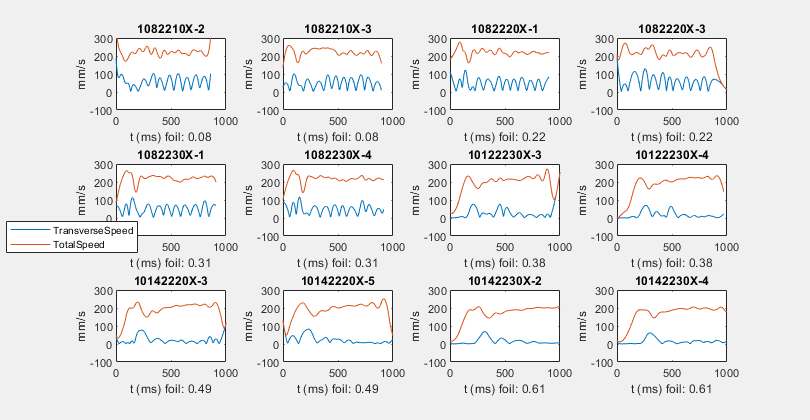

fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('TransverseSpeed10oil.fig')


figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i-12);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end

Tspeed =    43.5727
   35.3551
   28.4715
   22.9854
   18.9237
   16.1911
   14.4865
   13.3347
   12.2389
   10.8056


Tspeed =    39.1708
   33.7635
   28.5634
   23.5612
   18.7486
   14.1211
    9.6881
    5.5286
    2.4206
    4.0899


Tspeed =     4.2125
    3.1150
    2.1963
    1.4824
    1.0320
    0.9039
    0.9975
    1.1358
    1.2426
    1.3226


Tspeed =    28.0283
   20.7421
   14.1395
    8.2221
    3.0008
    1.6341
    5.4712
    8.6560
   11.1615
   12.9852


Tspeed =    37.5106
   33.9347
   30.5414
   27.3306
   24.3021
   21.4556
   18.7909
   16.3075
   14.0052
   11.8834


Tspeed =    10.1125
    7.2559
    4.6412
    2.2852
    0.5559
    1.9369
    3.5824
    5.0174
    6.2231
    7.1956


Tspeed =    12.7921
   10.2811
    7.9789
    5.8865
    4.0061
    2.3477
    0.9762
    0.7424
    1.6579
    2.5000


Tspeed =     6.3889
    4.3992
    2.6550
    1.1570
    0.1162
    1.1084
    1.8709
    2.3891
    2.6629
    2.6930


Tspeed =     5.0311
    3.8061
    2.7312
    1.8212
    1.1217
    0.7741
    0.8769
    1.1455
    1.3740
    1.5067


Tspeed =    11.6198
    8.6932
    6.0758
    3.8028
    2.0287
    1.5115
    2.4235
    3.5051
    4.4074
    5.0689


Tspeed =    22.0995
   20.5017
   18.9310
   17.3874
   15.8710
   14.3819
   12.9202
   11.4864
   10.0809
    8.7044


Tspeed =    27.0902
   21.6758
   16.7487
   12.3377
    8.5144
    5.4910
    3.9030
    4.3628
    5.8387
    7.3614


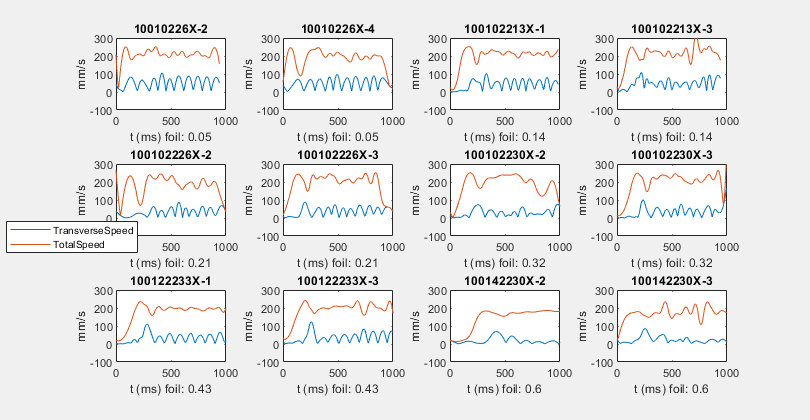

fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('TransverseSpeed100oil.fig')


figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(2,2,i-24);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end

Tspeed =    15.8627
   11.0672
    6.8853
    3.3169
    0.3651
    1.9826
    3.7130
    4.8326
    5.3435
    5.2500


Tspeed =    73.9851
   56.3197
   40.2597
   25.9208
   13.7952
    7.4345
   12.6449
   20.2784
   27.0225
   32.4314


Tspeed =   126.9003
  113.0271
   99.6140
   86.6612
   74.1686
   62.1367
   50.5658
   39.4567
   28.8116
   18.6366


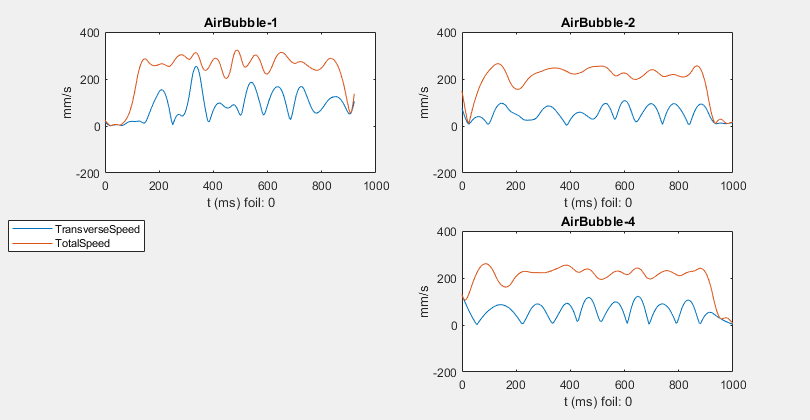

fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('TransverseSpeedAir.fig')

clear all
DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'

DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'

figure('visible','on');
clf;
for i = 1:5
    path = [DataPath, num2str(i), '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(2,3,i);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(num2str(i));
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel(['t (ms) ', 'foil: ', num2str(0)]);
        ylabel('mm/s');
    end
end

Tspeed =     6.5412
    5.0146
    3.6374
    2.4101
    1.3351
    0.4320
    0.4343
    1.0436
    1.5236
    1.8579


Tspeed =     2.0695
    1.6291
    1.2188
    0.8388
    0.4904
    0.1837
    0.1614
    0.4068
    0.6368
    0.8396


Tspeed =    14.1521
   10.4639
    7.1453
    4.1963
    1.6176
    0.5990
    2.4363
    3.9072
    5.0090
    5.7414


Tspeed =     1.2023
    0.8753
    0.5950
    0.3626
    0.1821
    0.0816
    0.1109
    0.1524
    0.1592
    0.1315


Tspeed =     8.7488
    6.5739
    4.6276
    2.9111
    1.4306
    0.3032
    0.9392
    1.7320
    2.3105
    2.6650


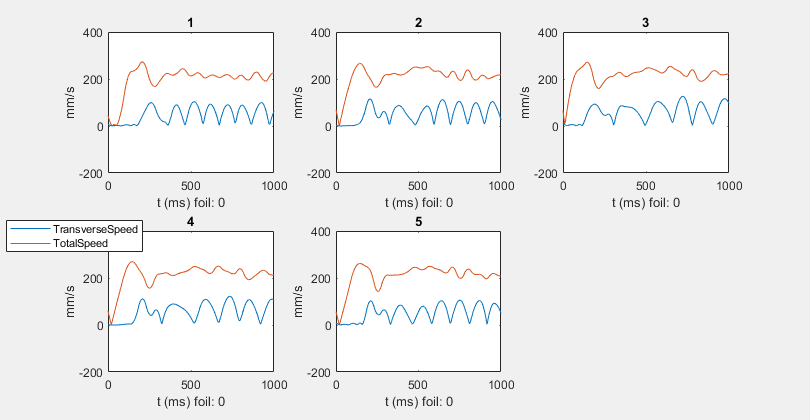

fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('TransverseSpeedAirNew.fig')

## Vertical Velocity

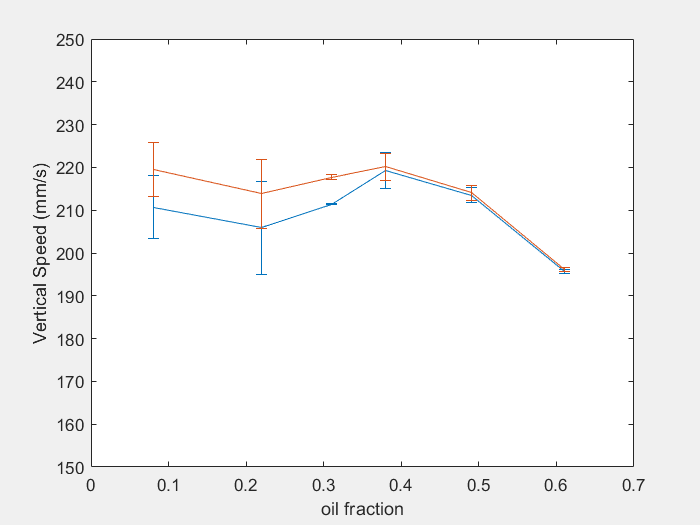

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
SpeedTableVertical = [];
SpeedTableTransverse = [];
figure('visible','on');
clf;
foilPlot = []; W = []; error = []; totalSpeed = []; totalError = [];
for i = 1:2:12
    path1 = [ReadingPath, FileName{i}, '.mat'];
    path2 = [ReadingPath, FileName{i + 1}, '.mat'];
    if isfile(path1)
        data = load(path1);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal1 = mean(Total);
        u1 = mean(w);
        k1 = mean(sqrt(u.^2 + v.^2));
        SpeedTableVertical = [SpeedTableVertical; u1];
        SpeedTableTransverse = [SpeedTableTransverse; k1];
    end
    if isfile(path2)
        data = load(path2);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal2 = mean(Total);
        u2 = mean(w);
        k2 = mean(sqrt(u.^2 + v.^2));
        SpeedTableVertical = [SpeedTableVertical; u2];
        SpeedTableTransverse = [SpeedTableTransverse; k2];
    end
    uCenter = (u1 + u2)/2;
    range = abs(u1 - u2);  
    foilPlot = [foilPlot, foil(i)];
    W = [W, uCenter];
    error = [error, range];
    tCenter = (meanTotal1 + meanTotal2)/2;
    tRange = abs(meanTotal2 - meanTotal1);
    totalSpeed = [totalSpeed, tCenter];
    totalError = [totalError, tRange];
end
errorbar(foilPlot,W,error);
hold on;
errorbar(foilPlot,totalSpeed, totalError);
hold off;
xlabel('oil fraction');
ylabel('Vertical Speed (mm/s)');
ylim([150,250]); xlim([0, 0.7]);
savefig('VerticalV10Oil.fig')

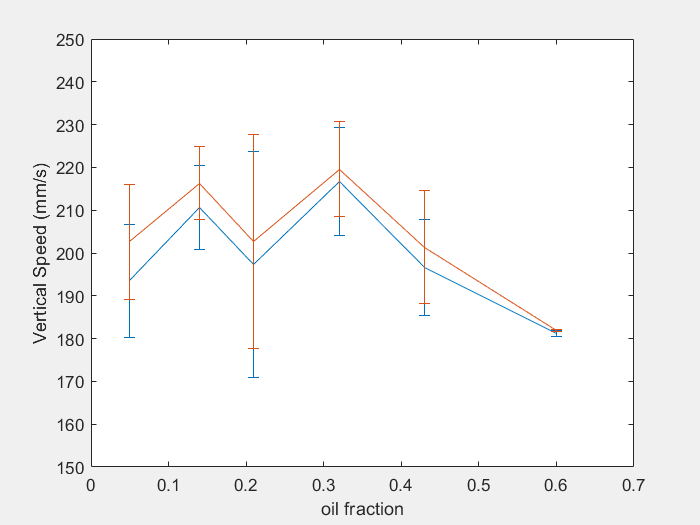


figure('visible','on');
clf;
foilPlot = []; W = []; error = [];totalSpeed = []; totalError = [];
for i = 13:2:24
    path1 = [ReadingPath, FileName{i}, '.mat'];
    path2 = [ReadingPath, FileName{i + 1}, '.mat'];
    if isfile(path1)
        data = load(path1);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal1 = mean(Total);
        u1 = mean(w);
        k1 = mean(sqrt(u.^2 + v.^2));
        SpeedTableVertical = [SpeedTableVertical; u1];
        SpeedTableTransverse = [SpeedTableTransverse; k1];
    end
    if isfile(path2)
        data = load(path2);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal2 = mean(Total);
        u2 = mean(w);
        k2 = mean(sqrt(u.^2 + v.^2));
        SpeedTableVertical = [SpeedTableVertical; u2];
        SpeedTableTransverse = [SpeedTableTransverse; k2];
    end
    uCenter = (u1 + u2)/2;
    range = abs(u1 - u2);  
    foilPlot = [foilPlot, foil(i)];
    W = [W, uCenter];
    error = [error, range];
    tCenter = (meanTotal1 + meanTotal2)/2;
    tRange = abs(meanTotal2 - meanTotal1);
    totalSpeed = [totalSpeed, tCenter];
    totalError = [totalError, tRange];
end
errorbar(foilPlot,W,error);
hold on;
errorbar(foilPlot,totalSpeed, totalError);
hold off;
xlabel('oil fraction');
ylabel('Vertical Speed (mm/s)');
ylim([150,250]); xlim([0, 0.7]);
savefig('VerticalV100Oil.fig')

clear all
DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'

DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'

figure('visible','on');
clf;
SpeedTableVertical = [];
SpeedTableTransverse = [];
for i = 1:5
    path = [DataPath, num2str(i), '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        z = traj3D(:,3)
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal2 = mean(Total);
        u2 = mean(w);
        k2 = mean(sqrt(u.^2 + v.^2));
        SpeedTableVertical = [SpeedTableVertical; u2];
        SpeedTableTransverse = [SpeedTableTransverse; k2];
    end
end

z =          0
    0.1530
    0.2579
    0.3222
    0.3535
    0.3592
    0.3469
    0.3242
    0.2986
    0.2776


z =          0
   -0.2408
   -0.4111
   -0.5123
   -0.5458
   -0.5131
   -0.4156
   -0.2547
   -0.0319
    0.2514


z =          0
   -0.1984
   -0.2800
   -0.2511
   -0.1177
    0.1138
    0.4372
    0.8463
    1.3350
    1.8968


z =          0
   -0.2071
   -0.3553
   -0.4450
   -0.4764
   -0.4500
   -0.3660
   -0.2249
   -0.0269
    0.2276


z =          0
   -0.1952
   -0.3381
   -0.4282
   -0.4655
   -0.4497
   -0.3806
   -0.2580
   -0.0815
    0.1489


## Wavelet

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
freq10 = [];
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i);
        %cwt(Tspeed,200);
        [ift,t] = instfreq(Tspeed,200);
        instfreq(Tspeed,200);
        freq = mean(ift);
        freq10 = [freq10, freq];
        xlabel({['Overall freq: ', num2str(freq)],['oil fraction: ', num2str(foil(i))]});
    end
end

Tspeed =   188.1593
  150.6163
  119.6475
   96.5905
   82.8623
   78.5260
   81.0863
   86.8338
   92.8058
   97.2000


Tspeed =    26.4712
   34.8284
   41.6506
   46.7068
   49.9136
   51.2342
   50.6504
   48.1523
   43.7356
   37.4002


Tspeed =   112.5326
  103.5990
   94.4401
   85.0436
   75.3982
   65.4934
   55.3204
   44.8722
   34.1476
   23.1619


Tspeed =   191.9548
  159.4342
  129.3162
  101.6011
   76.2892
   53.3814
   32.8806
   14.8024
    1.5857
   14.3177


Tspeed =    71.6794
   70.3757
   68.1867
   65.1054
   61.1270
   56.2496
   50.4741
   43.8065
   36.2631
   27.8884


Tspeed =    89.8480
   88.8598
   86.8019
   83.6537
   79.3995
   74.0272
   67.5282
   59.8964
   51.1288
   41.2279


Tspeed =     3.5239
    2.7377
    2.0571
    1.4912
    1.0634
    0.8226
    0.8057
    0.9489
    1.1602
    1.4023


Tspeed =     0.8069
    0.8402
    0.8774
    0.9123
    0.9405
    0.9592
    0.9661
    0.9599
    0.9397
    0.9048


Tspeed =    38.6588
   30.2682
   22.6195
   15.7141
    9.5566
    4.1732
    1.0323
    4.6311
    7.8114
   10.2727


Tspeed =   128.1713
  108.9820
   90.9136
   73.9665
   58.1416
   43.4406
   29.8683
   17.4410
    6.2847
    4.6644


Tspeed =     7.5288
    6.1830
    4.9502
    3.8302
    2.8229
    1.9290
    1.1517
    0.5128
    0.2960
    0.6601


Tspeed =     7.3024
    6.1359
    5.0553
    4.0605
    3.1513
    2.3275
    1.5889
    0.9354
    0.3691
    0.1463


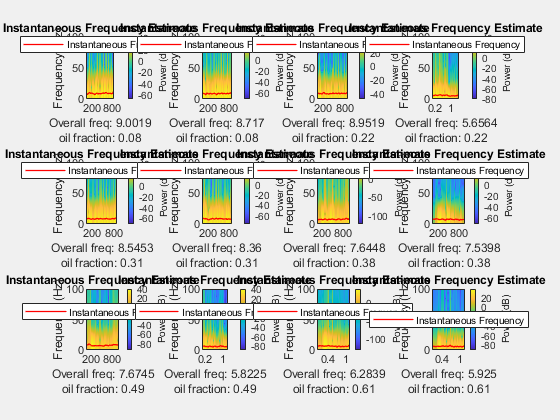

savefig('freq10oil.fig')

figure('visible','on');
clf;
freq100 = [];
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i - 12);
        %cwt(Tspeed,200);
        [ift,t] = instfreq(Tspeed,200);
        instfreq(Tspeed,200);
        freq = mean(ift);
        freq100 = [freq100, freq];
        xlabel({['Overall freq: ', num2str(freq)],['oil fraction: ', num2str(foil(i))]});
    end
end

Tspeed =    43.5727
   35.3551
   28.4715
   22.9854
   18.9237
   16.1911
   14.4865
   13.3347
   12.2389
   10.8056


Tspeed =    39.1708
   33.7635
   28.5634
   23.5612
   18.7486
   14.1211
    9.6881
    5.5286
    2.4206
    4.0899


Tspeed =     4.2125
    3.1150
    2.1963
    1.4824
    1.0320
    0.9039
    0.9975
    1.1358
    1.2426
    1.3226


Tspeed =    28.0283
   20.7421
   14.1395
    8.2221
    3.0008
    1.6341
    5.4712
    8.6560
   11.1615
   12.9852


Tspeed =    37.5106
   33.9347
   30.5414
   27.3306
   24.3021
   21.4556
   18.7909
   16.3075
   14.0052
   11.8834


Tspeed =    10.1125
    7.2559
    4.6412
    2.2852
    0.5559
    1.9369
    3.5824
    5.0174
    6.2231
    7.1956


Tspeed =    12.7921
   10.2811
    7.9789
    5.8865
    4.0061
    2.3477
    0.9762
    0.7424
    1.6579
    2.5000


Tspeed =     6.3889
    4.3992
    2.6550
    1.1570
    0.1162
    1.1084
    1.8709
    2.3891
    2.6629
    2.6930


Tspeed =     5.0311
    3.8061
    2.7312
    1.8212
    1.1217
    0.7741
    0.8769
    1.1455
    1.3740
    1.5067


Tspeed =    11.6198
    8.6932
    6.0758
    3.8028
    2.0287
    1.5115
    2.4235
    3.5051
    4.4074
    5.0689


Tspeed =    22.0995
   20.5017
   18.9310
   17.3874
   15.8710
   14.3819
   12.9202
   11.4864
   10.0809
    8.7044


Tspeed =    27.0902
   21.6758
   16.7487
   12.3377
    8.5144
    5.4910
    3.9030
    4.3628
    5.8387
    7.3614


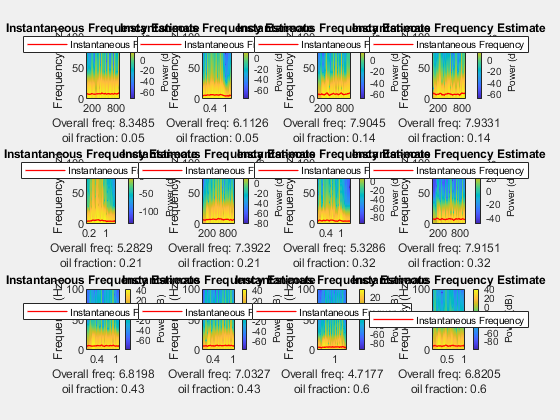

savefig('freq100oil.fig')

% figure('visible','on');
% clf;
% for i = 25:28
%     path = [ReadingPath, FileName{i}, '.mat'];
%     if isfile(path)
%         data = load(path);
%         traj3D = data.traj3D;
%         u = -traj3D(:,4);
%         v = traj3D(:,5);
%         w = traj3D(:,6);
%         xplot = (0:(length(u)-1))*1/200 * 1000;
%         speed = sqrt(u.^2 + v.^2 + w.^2);
%         Tspeed = sqrt(u.^2 + v.^2)
%         subplot(2,2,i - 24);
%         %cwt(Tspeed,200);
%         [ift,t] = instfreq(Tspeed,200);
%         instfreq(Tspeed,200);
%         freq = mean(ift);
%         xlabel({['Overall freq: ', num2str(freq)],['oil fraction: ', num2str(foil(i))]});
%     end
% end
% savefig('freqAir.fig')


DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'

DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'

figure('visible','on');
clf;
freqAir = []


freqAir =

     []



for i = 1:5
    path = [DataPath, num2str(i), '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(2,3,i);
        %cwt(Tspeed,200);
        [ift,t] = instfreq(Tspeed,200);
        instfreq(Tspeed,200);
        freq = mean(ift);
        freqAir = [freqAir, freq];
        xlabel({['Overall freq: ', num2str(freq)],['oil fraction: ', num2str(0)]});
    end
end

Tspeed =     6.5412
    5.0146
    3.6374
    2.4101
    1.3351
    0.4320
    0.4343
    1.0436
    1.5236
    1.8579


Tspeed =     2.0695
    1.6291
    1.2188
    0.8388
    0.4904
    0.1837
    0.1614
    0.4068
    0.6368
    0.8396


Tspeed =    14.1521
   10.4639
    7.1453
    4.1963
    1.6176
    0.5990
    2.4363
    3.9072
    5.0090
    5.7414


Tspeed =     1.2023
    0.8753
    0.5950
    0.3626
    0.1821
    0.0816
    0.1109
    0.1524
    0.1592
    0.1315


Tspeed =     8.7488
    6.5739
    4.6276
    2.9111
    1.4306
    0.3032
    0.9392
    1.7320
    2.3105
    2.6650


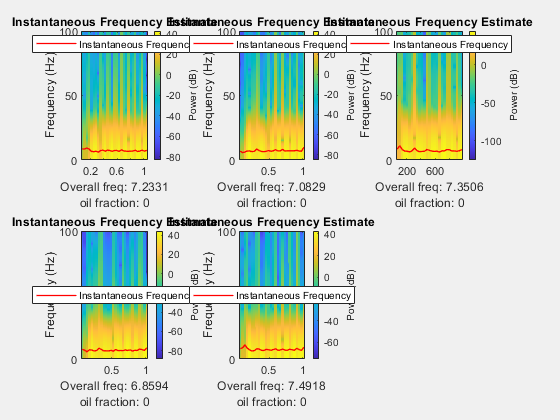

savefig('freqAirNew.fig')

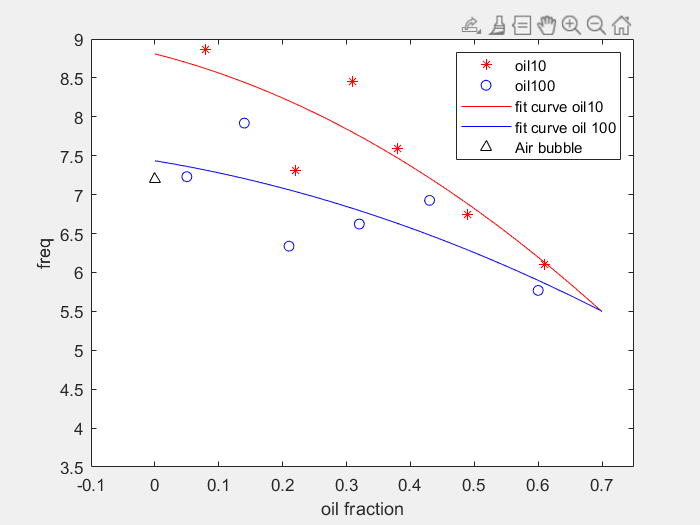

figure('visible','on');
clf;
foil10 = [0.08, 0.22, 0.31, 0.38, 0.49, 0.61];
foil100 = [0.05, 0.14, 0.21, 0.32, 0.43, 0.6];
freq10mean = [];
freq100mean = [];
for i = 1:6
    index = i*2 - 1;
    freq10mean = [freq10mean, (freq10(index) + freq10(index + 1))/2];
    freq100mean = [freq100mean, (freq100(index) + freq100(index + 1))/2];
end
plot(foil10, freq10mean, 'r*');
hold on;
plot(foil100, freq100mean, 'bo');
hold on;

[population2,gof] = fit(foil10',freq10mean','poly2');
plot(population2', 'r');
hold on;
[population2,gof] = fit(foil100',freq100mean','poly2');
plot(population2, 'b');

hold on;
plot([0], mean(freqAir), 'k^');

xlabel('oil fraction');
ylabel('freq');
legend('oil10', 'oil100', 'fit curve oil10', 'fit curve oil 100', 'Air bubble');
xlim([-0.1,0.75]);
ylim([3.5, 9]);
savefig('freqCompare.fig')


figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i-12);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('WaveLet100oil.fig')

figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(2,2,i-24);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('WaveLetAir.fig')


## transverse position amplitude

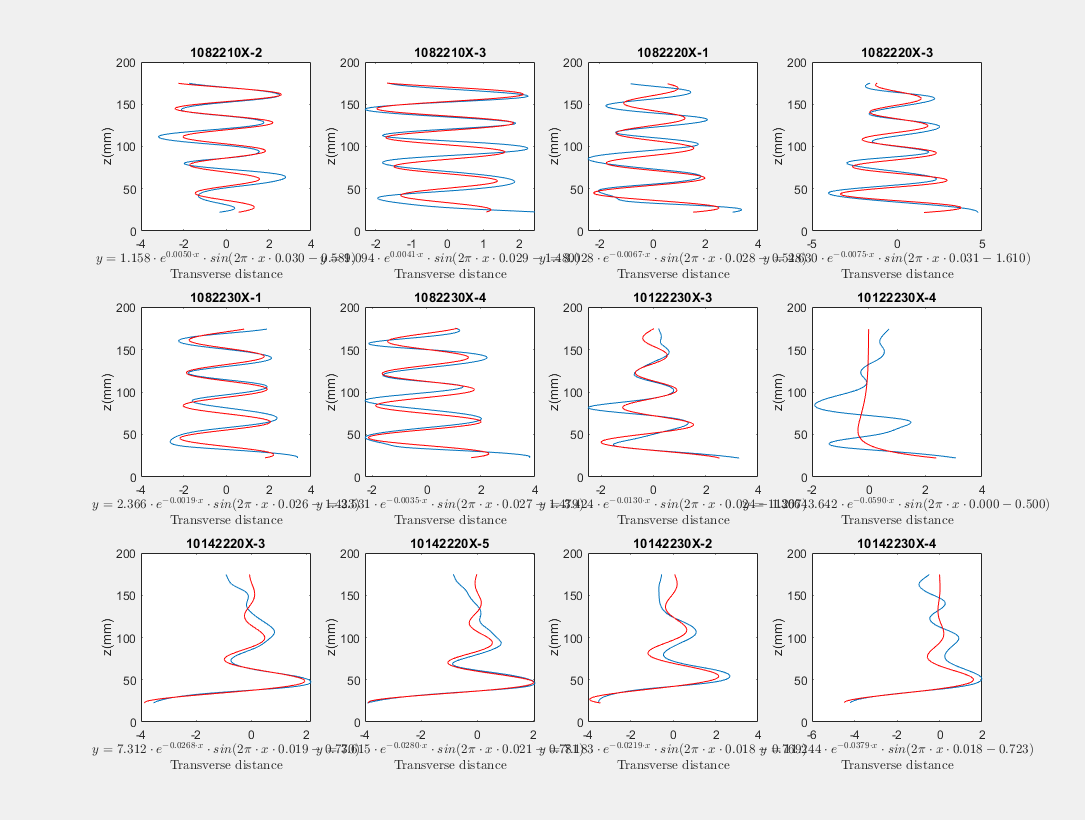

clear all;
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
freq10 = [];
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane; a = Plane(1); b = Plane(2); d = Plane(3);
        x0 = 0; y0 = (d - a * x0) / b;
        x1 = 1; y1 = (d - a * x1) / b;
        vector = [x0,y0;x1,y1];
        for k = 1:length(traj3D)
            q = traj3D(k,1:2);
            p = proj(vector,q);
            traj3D(k,1:2) = p;
        end
        subplot(3,4,i);
        x = traj3D(:,1); x = x - x(1);
        y = traj3D(:,2); y = y - y(1);
        z = traj3D(:,3);
        Tdistance = sqrt(x.^2 + y.^2);
       
        for k = 1:length(Tdistance)
            if x(k) > 0
                Tdistance(k) = -1 * Tdistance(k);
            end
        end
       
        MaxID = min(find(z>174));
        MinID = max(find(z<23));
        Tdistance = detrend(Tdistance(MinID:MaxID));
        
        plot(Tdistance, z(MinID:MaxID));
        t = [1:length(z)] * 5;
        
        result = fitDamping(z(MinID:MaxID),Tdistance);
        xp = linspace(min(z(MinID:MaxID)),max(z(MinID:MaxID)), 500);
        hold on;
        fit = @(b,x)  b(1) .* exp(b(2).*x) .* (sin(2*pi*x./b(3) + 2*pi/b(4))) + b(5); 
        plot(fit(result,xp),xp, '-r');
        title(FileName{i});
        ylabel('z(mm)');
        xlabel({sprintf('$y = %.3f\\cdot e^{%.4f\\cdot x}\\cdot sin(2\\pi\\cdot x\\cdot %.3f%.3f)$', [result(1:2); 1./result(3:4)]);'Transverse distance' }, 'Interpreter','latex')
    end
end
savefig('TransverseSpeedAmplitude10oil.fig')


figure('visible','on');
clf;
freq10 = [];
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane; a = Plane(1); b = Plane(2); d = Plane(3);
        x0 = 0; y0 = (d - a * x0) / b;
        x1 = 1; y1 = (d - a * x1) / b;
        vector = [x0,y0;x1,y1];
        for k = 1:length(traj3D)
            q = traj3D(k,1:2);
            p = proj(vector,q);
            traj3D(k,1:2) = p;
        end
        subplot(3,4,i - 12);
        x = traj3D(:,1); x = x - x(1);
        y = traj3D(:,2); y = y - y(1);
        z = traj3D(:,3);
        Tdistance = sqrt(x.^2 + y.^2);
       
        for k = 1:length(Tdistance)
            if x(k) > 0
                Tdistance(k) = -1 * Tdistance(k);
            end
        end
       
        MaxID = min(find(z>174));
        MinID = max(find(z<23));
        Tdistance = detrend(Tdistance(MinID:MaxID));
        
        plot(Tdistance, z(MinID:MaxID));
        try
            t = [1:length(z)] * 5;
        
            result = fitDamping(z(MinID:MaxID),Tdistance);
            xp = linspace(min(z(MinID:MaxID)),max(z(MinID:MaxID)), 500);
            hold on;
            fit = @(b,x)  b(1) .* exp(b(2).*x) .* (sin(2*pi*x./b(3) + 2*pi/b(4))) + b(5); 
            plot(fit(result,xp),xp, '-r');
       
            ylabel('z(mm)');
            xlabel({sprintf('$y = %.3f\\cdot e^{%.4f\\cdot x}\\cdot sin(2\\pi\\cdot x\\cdot %.3f%.3f)$', [result(1:2); 1./result(3:4)]);'Transverse distance' }, 'Interpreter','latex')
        catch
        end
        title(FileName{i});
    end
end

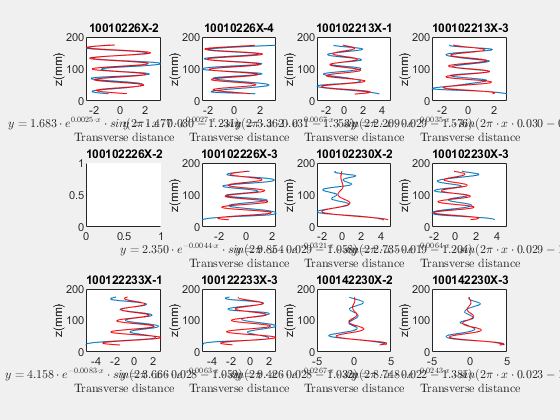

savefig('TransverseSpeedAmplitude100oil.fig')

function [ProjPoint] = proj(vector, q)
    p0 = vector(1,:);
    p1 = vector(2,:);
    a = [-q(1)*(p1(1)-p0(1)) - q(2)*(p1(2)-p0(2)); ...
        -p0(2)*(p1(1)-p0(1)) + p0(1)*(p1(2)-p0(2))]; 
    b = [p1(1) - p0(1), p1(2) - p0(2);...
        p0(2) - p1(2), p1(1) - p0(1)];
    ProjPoint = -(b\a);
end
function [f, P1] = findAmplitude(X, Fs)
    L = length(X);
    Y = fft(X);
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(L/2))/L;
end
function result = fitDamping(x,y)
    y = detrend(y);                                                                 % Remove Linear Trend
    yu = max(y);
    yl = min(y);
    yr = (yu-yl);                                                                   % Range of ‘y’
    yz = y-yu+(yr/2);
    zci = @(v) find(v(:).*circshift(v(:), [-1 0]) <= 0);                            % Returns Approximate Zero-Crossing Indices Of Argument Vector
    zt = x(zci(y));
    per = 2*mean(diff(zt));                                                         % Estimate period
    ym = mean(y);                                                                   % Estimate offset
    fit = @(b,x)  b(1) .* exp(b(2).*x) .* (sin(2*pi*x./b(3) + 2*pi/b(4))) + b(5);        % Objective Function to fit
    fcn = @(b) norm(fit(b,x) - y);    
    options = optimset('MaxFunEvals',50000, 'MaxIter', 500*500); % Least-Squares cost function
    [result,nmrs] = fminsearch(fcn, [yr; -0.5;  per;  -1;  ym], options);
end